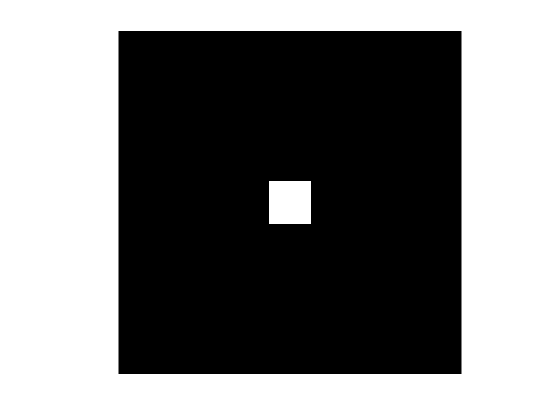

F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
showgrey(F .* G); 

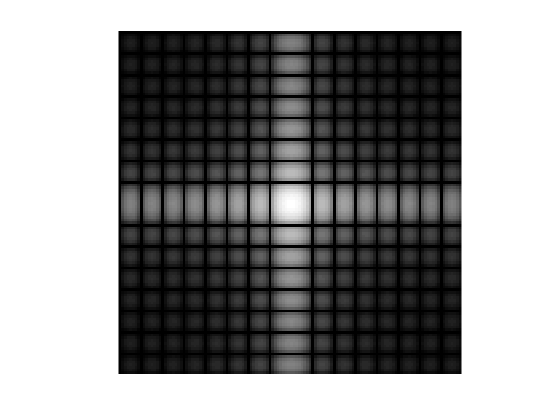

showfs(fft2(F .* G))

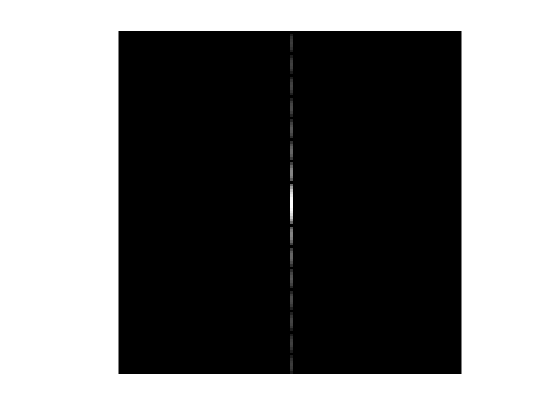


Fhat = 1/128.*(fft2(F));
Ghat = 1/128.*(fft2(G));
showfs(Fhat);

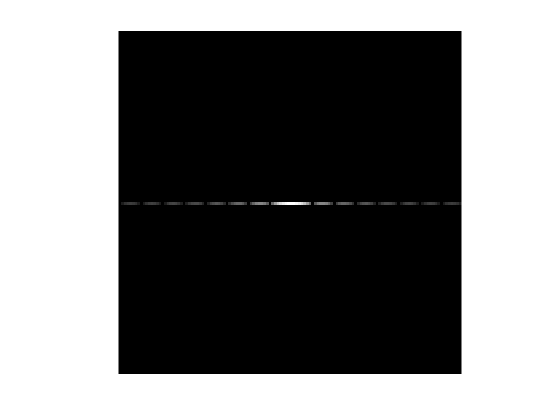

showfs(Ghat);

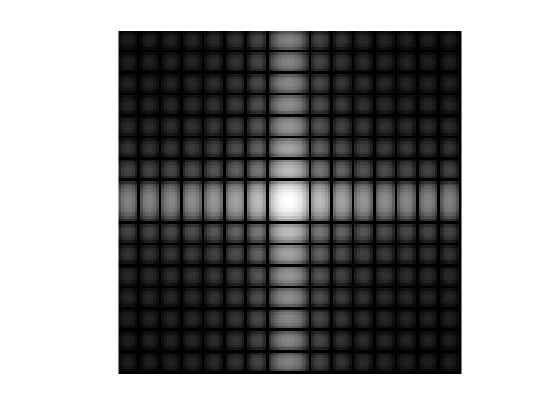

convd = fftshift(filter2(fftshift(Fhat), fftshift(Ghat)));
showfs(convd)